# Import data from text file P1

Script for importing data from the following text file:

Auto-generated by MATLAB on 26-Jun-2020 15:52:00

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["x", "y", "z", "Name", "Colourred", "Colourgreen", "Colourblue"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Name", "TrimNonNumeric", true);
opts = setvaropts(opts, "Name", "ThousandsSeparator", ",");

% Import the data
P1line = readtable("P1line.dat", opts);

## Convert to output type

P1line = table2cell(P1line);
numIdx = cellfun(@(x) ~isnan(str2double(x)), P1line);
P1line(numIdx) = cellfun(@(x) {str2double(x)}, P1line(numIdx))

P1line = 164×7 cell array
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0]}    {[85]}    {[0]}
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0]}    {[85]}    {[0]}
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0]}    {[85]}    {[0]}
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0]}    {[85]}    {[0]}
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0]}    {[85]}    {[0]}
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0]}    {[85]}    {[0]}
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0]}    {[85]}    {[0]}
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0]}    {[85]}    {[0]}
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0]}    {[85]}    {[0]}
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0]}    {[85]}    {[0]}
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0]}    {[85]}    {[0]}
    {[5.0824e+05]}    {[5.9000e+06]}    {[0]}    {[1]}    {[0

## Clear temporary variables

clear opts

# Import data from text file P2

Script for importing data from the following text file:

Auto-generated by MATLAB on 26-Jun-2020 15:52:00

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["x", "y", "z", "Name", "Colourred", "Colourgreen", "Colourblue"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Name", "TrimNonNumeric", true);
opts = setvaropts(opts, "Name", "ThousandsSeparator", ",");

% Import the data
P2line = readtable("P2line.dat", opts);

## Convert to output type

P2line = table2cell(P2line);
numIdx = cellfun(@(x) ~isnan(str2double(x)), P2line);
P2line(numIdx) = cellfun(@(x) {str2double(x)}, P2line(numIdx))

P2line = 97×7 cell array
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[2]}    {[0]}    {[140]}    {[0]}
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[2]}    {[0]}    {[140]}    {[0]}
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[2]}    {[0]}    {[140]}    {[0]}
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[2]}    {[0]}    {[140]}    {[0]}
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[2]}    {[0]}    {[140]}    {[0]}
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[2]}    {[0]}    {[140]}    {[0]}
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[2]}    {[0]}    {[140]}    {[0]}
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[2]}    {[0]}    {[140]}    {[0]}
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[2]}    {[0]}    {[140]}    {[0]}
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[2]}    {[0]}    {[140]}    {[0]}
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[2]}    {[0]}    {[140]}    {[0]}
    {[5.0822e+05]}    {[5.8999e+06]}    {[0]}    {[

## Clear temporary variables

clear opts

# Plotting polygons

% Plotting polygon P1 with centroid
fill(cell2mat(P1line(:,1)), cell2mat(P1line(:,2)), 'b');
P1 = polyshape(cell2mat(P1line(:,1)),cell2mat(P1line(:,2)))

P1 =   polyshape with properties:

      Vertices: [150×2 double]
    NumRegions: 1
      NumHoles: 0


% xlim([507000 508400]) % values for the original full dyke map
% ylim([5898400 5900200]) % values for the original full dyke map
axis equal
[x,y] = centroid(P1) % Centerpoint of the polygon

x = 5.0822e+05

y = 5.9000e+06

B_P1 = boundary(P1);
test = pdist(B_P1)

test =     0.3043    0.7826    1.4783    1.4783    1.8697    1.7827    1.5653    1.4783    1.4783    1.5218    1.5218    1.5653    1.8262    1.3479    1.3479    1.2609    1.2609    0.8261    0.5217    1.5219    3.5221    5.3918    5.7832    6.0875    6.7398    7.4790    8.6965    9.8270   11.3923   13.0447   16.1754   15.7840   15.2622   15.2188   15.6101   15.5666   15.5666   15.0883   15.0448   15.0014   13.9578   12.9577   12.9142   12.9142   13.1316   13.1316   13.8273   14.0447   14.8274   15.6101


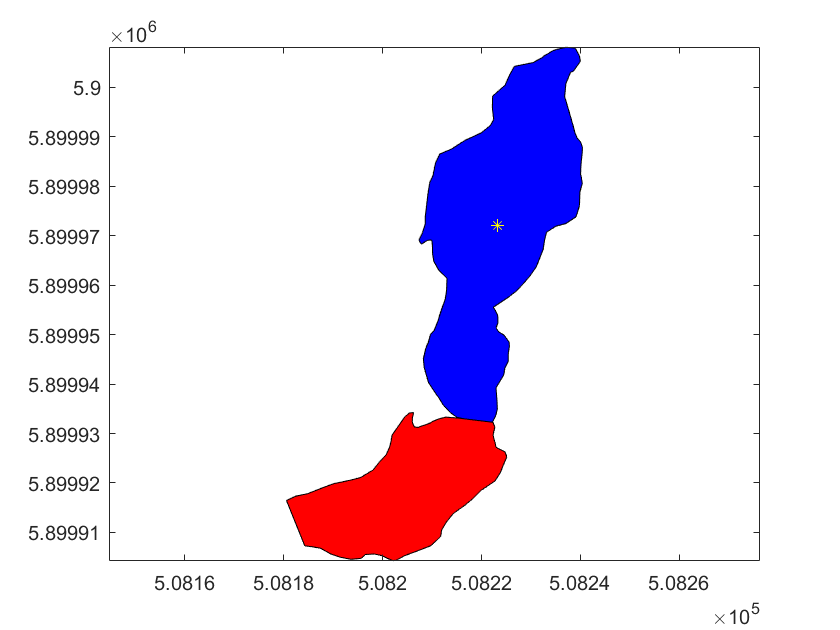

hold on
% plotting polygon P2
fill(cell2mat(P2line(:,1)), cell2mat(P2line(:,2)),'r')
plot(x,y,'y*')
axis equal

% 
% 
% 
% 
% 
% 
% 
% %% Imageway
% tiff_image = imread('Segment_overview2.tif');
% if ndims(tiff_image) > 3
%   error('got tiff image with more than 3 dimensions???');
% end
% if size(tiff_image,3) == 4
%   tiff_image = tiff_image(:,:,1:3);
% elseif size(tiff_image,3) == 1
%   tiff_image = tiff_image(:,:,[1 1 1]);  %grayscale to rgb
% elseif size(tiff_image,3) ~= 3
%   error('expected tiff image to have 1 channel, or 3 channels, or 4 channels, got %d\n', size(tiff_image,3));
% end
% 
% [J, rect] = imcrop(tiff_image, [633.5 126.5 693 897]);

## test

% 
% imshow(J);
% I = rgb2gray(J);
% level = graythresh(J);
% imshow(I);
% 
% level_P1 = 0.1961;
% BW = imbinarize(I, level_P1)
% imshow(BW);
% 
% level_P2 = 0.3216;
% BW = imbinarize(I, level_P2)
% imshow(BW);
% binaryImage1 = grayImage >= 0.3215*255 & grayImage <= 0.3217*255;
% 
% areaFraction1 = sum(binaryImage1(:)) / numel(grayImage);
% imshow(binaryImage1)
% 
% 
% level_P3 = 0.4902;
% BW = imbinarize(I, level_P3)
% imshow(BW);
% level_P4 = 0.6745;
% BW = imbinarize(I, level_P4)
% imshow(BW);
% level_P5 = 0.6902;
% BW = imbinarize(I, level_P5)
% imshow(BW);
% level_P6 = 0.4941;
% BW = imbinarize(I, level_P6)
% imshow(BW);
% level_P7 = 0.298;
% BW = imbinarize(I, level_P7)
% imshow(BW);
% level_P8 = 0.2;
% BW = imbinarize(I, level_P8)
% imshow(BW);
% % BW = im2bw(J, 0.9);
% % BW1 = im2bw(J, 0.7);
% % subplot(2,1,1)
% % imshow(BW);
% % subplot(2,1,2)
% % imshow(BW1);
% 
% 